clc; clear; close all;

# 2D-FC Solver for Parameterized C2-type Patch Demo

f = @(x, y) exp(2*x.^2 + y.^2)

f = function_handle with value:
    @(x,y)exp(2*x.^2+y.^2)



% data given in S-type patch
n = 200;
h = 1./(n-1);
D_mesh = 0:h:1;
C = 27;
d = 10;

[X, Y] = meshgrid(D_mesh)

X =          0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462
         0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0

Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0

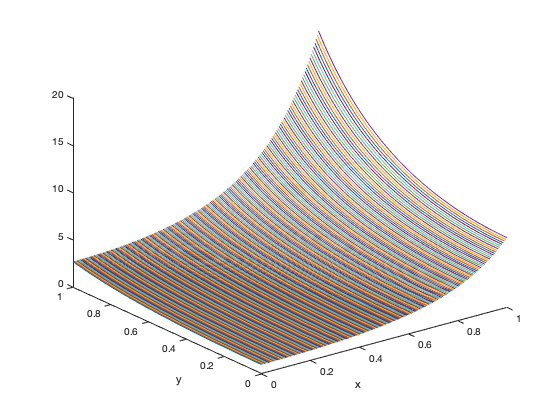

f_xy = f(X, Y);

figure;
plot3(X, Y, f_xy);
xlabel('x')
ylabel('y')


D_mesh_FC = -C*h:h:1;
[X_FC, Y_FC] = meshgrid(D_mesh_FC)

X_FC =    -0.1357   -0.1307   -0.1256   -0.1206   -0.1156   -0.1106   -0.1055   -0.1005   -0.0955   -0.0905   -0.0854   -0.0804   -0.0754   -0.0704   -0.0653   -0.0603   -0.0553   -0.0503   -0.0452   -0.0402   -0.0352   -0.0302   -0.0251   -0.0201   -0.0151   -0.0101   -0.0050         0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106
   -0.1357   -0.1307   -0.1256   -0.1206   -0.1156   -0.1106   -0.1055   -0.1005   -0.0955   -0.0905   -0.0854   -0.0804   -0.0754   -0.0704   -0.0653   -0.0603   -0.0553   -0.0503   -0.0452   -0.0402   -0.0352   -0.0302   -0.0251   -0.0201   -0.0151   -0.0101   -0.0050         0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055  

Y_FC =    -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357
   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307  

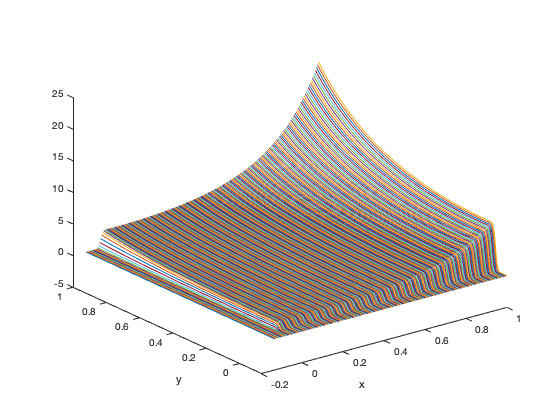


load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

fcont = fcont_gram_blend_C2(f_xy, d, A, Q);

figure;
plot3(X_FC, Y_FC, fcont)
xlabel('x')
ylabel('y')

# General C2-type Patch

f = @(x, y) exp(x.^2 + y.^2).*sin(x);
n_theta = 400;
theta_mesh = transpose(linspace(0, 2*pi, n_theta))

theta_mesh =          0
    0.0157
    0.0315
    0.0472
    0.0630
    0.0787
    0.0945
    0.1102
    0.1260
    0.1417



l_theta = @(theta) [2*sin(theta/2), -sin(theta)]

l_theta = function_handle with value:
    @(theta)[2*sin(theta/2),-sin(theta)]


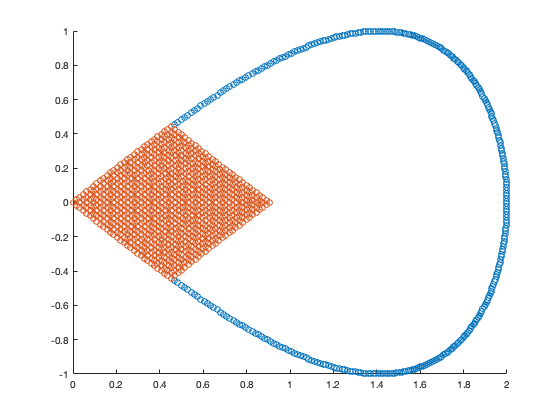

boundary_xy = l_theta(theta_mesh);

figure;
scatter(boundary_xy(:, 1), boundary_xy(:, 2));
hold on;

% number of points on each side of corner we use
n_eta = 30;
n_xi = 30;

h_eta = 1/(n_eta - 1);
h_xi = 1/(n_xi - 1);

% thetas of each corner
theta_a = theta_mesh(n_xi);
theta_b = theta_mesh(end-n_eta+1);
theta_c = 0;

% parameter mapping
l_A = @(xi) xi*(theta_a);
l_B = @(eta) eta*(theta_b-2*pi) + 2*pi;

M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_c);

% eta and xi meshes
eta_mesh = transpose(linspace(0, 1, n_eta));
xi_mesh = transpose(linspace(0, 1, n_xi));

[ETA, XI] = meshgrid(eta_mesh, xi_mesh);
corner_xy = M_p(XI(:), ETA(:));
scatter(corner_xy(:, 1), corner_xy(:, 2))

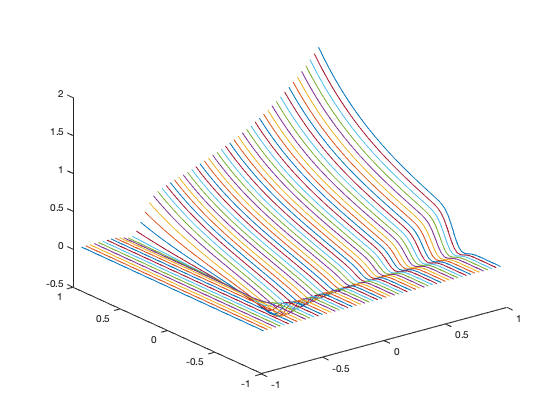

f_xy = reshape(f(corner_xy(:, 1), corner_xy(:, 2)), size(ETA));

fcont = fcont_gram_blend_C2(f_xy, d, A, Q);
cont_eta_mesh = transpose(-C*h_eta:h_eta:1);
cont_xi_mesh = transpose(-C*h_eta:h_eta:1);

[CONT_ETA, CONT_XI] = meshgrid(cont_eta_mesh, cont_xi_mesh);

% in parameter space
figure;
plot3(CONT_ETA, CONT_XI, fcont);

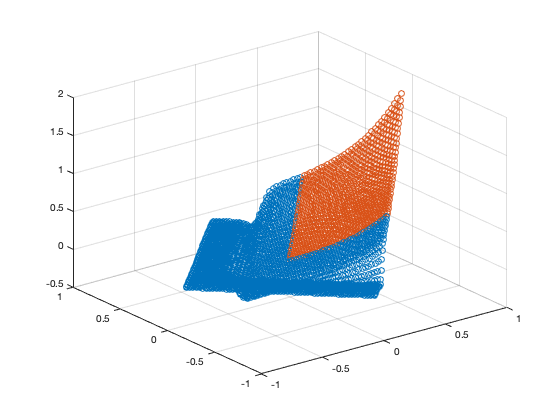


figure;
cont_xy = M_p(CONT_XI(:), CONT_ETA(:));
figure;
scatter3(cont_xy(:, 1), cont_xy(:, 2), fcont(:))
hold on;
scatter3(corner_xy(:, 1), corner_xy(:, 2), f(corner_xy(:, 1), corner_xy(:, 2)))

# Interpolation onto Cartesian Grid

% use normals to calculate what patch it belongs to
% construct mask for patches
R_grid = transpose(linspace(-1, 1, 50)); %"fake grid for testing this patch"
[R_x, R_y] = meshgrid(R_grid);
R_fcont = zeros(size(R_x));

J = @(v) [theta_a*cos(v(1)*theta_a/2) (theta_b-2*pi)*cos((v(2)*(theta_b-2*pi)+2*pi)/2); -theta_a*cos(v(1)*theta_a) -(theta_b-2*pi)*cos(v(2)*(theta_b-2*pi)+2*pi)];
err_guess = @(x, y, v) transpose(M_p(v(1), v(2))) - [x; y];
v_guess = newton_solve(@(v) err_guess(-0.8, 0.45, v), J, [0; 0], 1e-15, 100)

v_guess =    -1.4305
   -0.3470


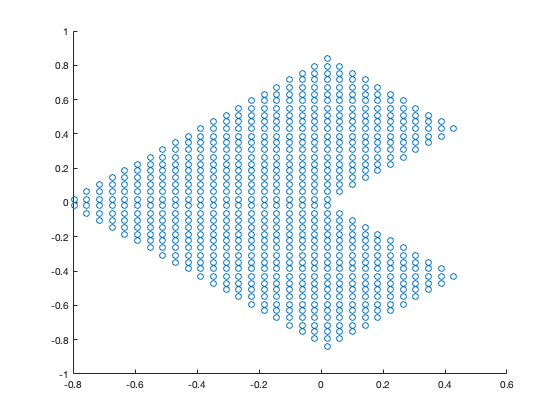


% TODO: don't have to use entire block, can restrict to enclosing rectangle of
% continued region

min_xy = min(cont_xy, [], 1);
max_xy = max(cont_xy, [], 1);
R_patch_msk = R_x <= max_xy(1) & R_x >= min_xy(1) & R_y <= max_xy(2) & R_y >= min_xy(2);

R_patch_x = R_x(R_patch_msk);
R_patch_y = R_y(R_patch_msk);

R_patch_idx = transpose((1:numel(R_x)));
R_patch_idx = R_patch_idx(R_patch_msk);

% using for loop right now, can vectorize using block matrix and flattened
% vectors later
R_xi = zeros(size(R_patch_x));
R_eta = zeros(size(R_patch_x));

for i = 1:length(R_xi)
    v_guess = newton_solve(@(v) err_guess(R_patch_x(i), R_patch_y(i), v), J, [0; 0], 1e-14, 100);
    R_xi(i) = v_guess(1);
    R_eta(i) = v_guess(2);
end

bound_msk_xi = R_xi <= max(cont_xi_mesh) & R_xi >= min(cont_xi_mesh);
bound_msk_eta = R_eta <= max(cont_eta_mesh) & R_eta >= min(cont_eta_mesh);
bound_msk = bound_msk_xi & bound_msk_eta;
interior_msk = R_xi <= 1 & R_xi >= 0 & R_eta <= 1 & R_eta >= 0;

figure;
scatter(R_patch_x(bound_msk & ~interior_msk), R_patch_y(bound_msk & ~interior_msk))

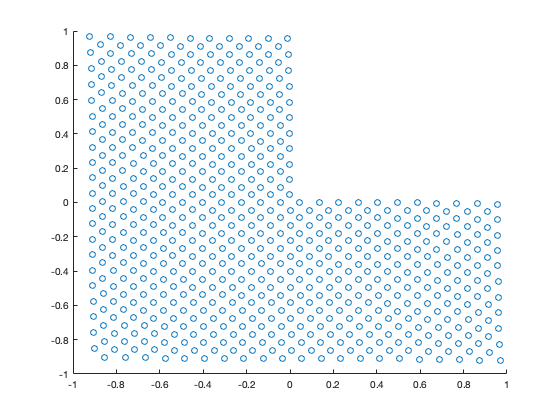


figure;
scatter(R_xi(bound_msk & ~interior_msk), R_eta(bound_msk & ~interior_msk))

patch_xi = R_xi(bound_msk);
patch_eta = R_eta(bound_msk);

patch_x = R_patch_x(bound_msk);
patch_y = R_patch_y(bound_msk);

% treat as vector, only need 1 for loop
% 2 step interpolation of degree 3, assumes odd interpolation degree
interpol_d = 3;
R_patch_fcont = zeros(size(R_patch_x));

patch_fcont = zeros(size(patch_xi));
for i=1:length(patch_xi)
    xi = patch_xi(i);
    eta = patch_eta(i);
    
    % interior
    if xi <= 1 & xi >= 0 & eta <= 1 & eta >= 0
        patch_fcont(i) = f(patch_x(i), patch_y(i));
    else
        % computes closest j value to left
        xi_j = floor((xi+C*h_xi)/h_xi) + 1;
        eta_j = floor((eta+C*h_eta)/h_eta) + 1;
        
        on_xi_grid = xi-(-C*h_xi+(xi_j-1)*h_xi) < eps;
        on_eta_grid = eta-(-C*h_eta+(eta_j-1)*h_eta) < eps;
        
        interpol_xi_j_mesh = transpose(xi_j-(interpol_d+1)/2+1:xi_j+(interpol_d+1)/2);
        interpol_eta_j_mesh = transpose(eta_j-(interpol_d+1)/2+1:eta_j+(interpol_d+1)/2);
        
        % boundary edge cases, shifts points to be within bounds
        interpol_xi_j_mesh = shift_idx_mesh(interpol_xi_j_mesh, 1, length(cont_xi_mesh));
        interpol_eta_j_mesh = shift_idx_mesh(interpol_eta_j_mesh, 1, length(cont_eta_mesh));
        
        interpol_xi_mesh = cont_xi_mesh(interpol_xi_j_mesh);
        interpol_eta_mesh = cont_eta_mesh(interpol_eta_j_mesh);
        % if corresponds to grid value, we don't need to interpolate
        if on_xi_grid && on_eta_grid
            patch_fcont(i) = fcont(xi_j, eta_j);
        else
            interpol_xi_points = zeros(size(interpol_xi_j_mesh));
            for vert_i=1:length(interpol_xi_points)
                interpol_coeff = polyfit(interpol_eta_mesh, fcont(interpol_xi_j_mesh(vert_i), interpol_eta_j_mesh), interpol_d);
                interpol_xi_points(vert_i) = polyval(interpol_coeff, eta);
            end
            interpol_coeff = polyfit(interpol_xi_mesh, interpol_xi_points, interpol_d);
            patch_fcont(i) = polyval(interpol_coeff, xi);
        end
    end
end
R_patch_fcont(bound_msk) = patch_fcont; % smallest rectangle surrounding patch
R_fcont(R_patch_idx(bound_msk)) = patch_fcont % smallest rectangle surrounding entire continued domain

R_fcont =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

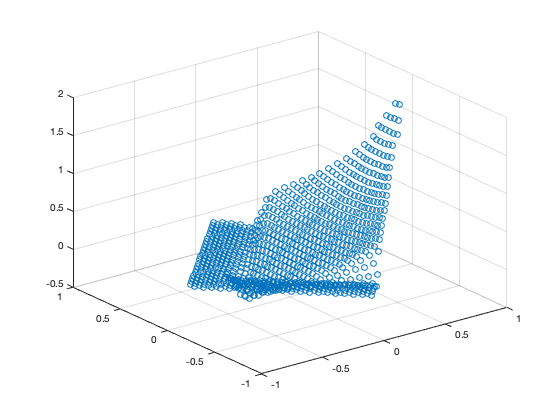


figure;
scatter3(R_patch_x(bound_msk), R_patch_y(bound_msk), patch_fcont);

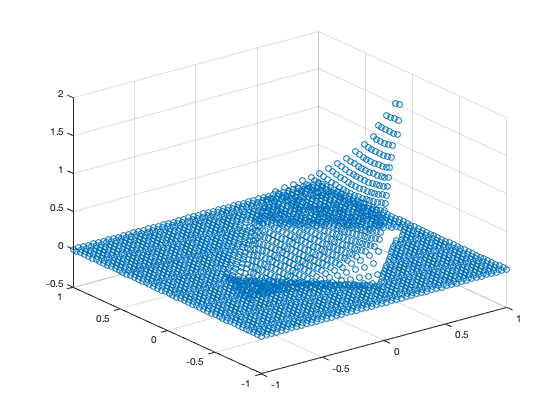


figure;
scatter3(R_x(:), R_y(:), R_fcont(:));

function idx_mesh = shift_idx_mesh(idx_mesh, min_bound, max_bound)
    if idx_mesh(1) < min_bound
            idx_mesh = idx_mesh + min_bound - idx_mesh(1);
    end
    if idx_mesh(end) > max_bound
            idx_mesh = idx_mesh + max_bound - idx_mesh(end);
    end
end